s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties



%Datos del regulador
Vg = 28;
Vo = 15;
R = 3;
fsw = 200e3;
C = 2.2e-3;
rc = 78e-3;
L = 25e-6;
Vpv = 2;
Vref = 2.5;
%Realimentacion
Ra = 10e3;
Rb = (Vref/Vo)*Ra / (1 - Vref/Vo);

%Datos del controlador
fc = 2e3

fc = 2000

R11 = 50e3

R11 = 50000

G_2k = -3.39675

G_2k = -3.3967


%Lazo abierto
P = Vg * ((R + s*rc*R*C)/(s^2*L*C*(R + rc) + s*(R*C*rc + L) + R));
M = 1/Vpv;
H = R2/(R1 + R2);

FDT_LA = P * M * H

FDT_LA =
 
         0.004308 s + 25.1
  -------------------------------
  1.693e-07 s^2 + 0.0005398 s + 3
 
Continuous-time transfer function.
Model Properties


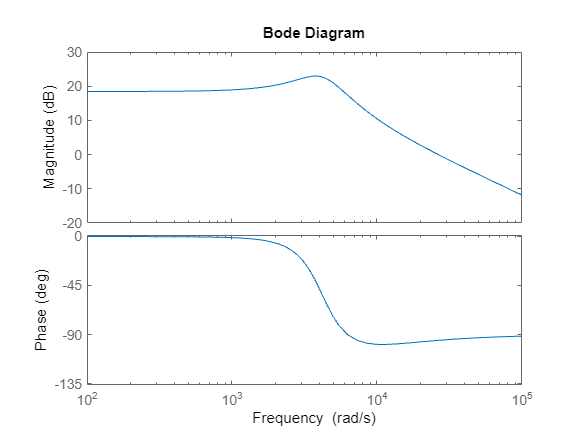


bode(FDT_LA)


%Calculos regulador
K = tan(1/4 * (pi/2 + pi/3 + 1.724))    %fc de 2k

K = 1.8962

%K = tan(1/4 * (pi/2 + pi/3 + 1.612))    %fc de 10k
tr = 10^(G_2k/20)      %fc de 2k

tr = 0.6763

%tr = 10^(-18.801/20)    %fc de 10k
R1 = R11/(K^2 - 1)

R1 = 1.9263e+04

C1 = 1/(2*pi*fc*R1*K)

C1 = 2.1786e-09

C3 = abs(tr/(2*pi*fc*R11))

C3 = 1.0764e-09

C2 = abs(tr)*K^2/(2*pi*fc*R11) - C3

C2 = 2.7940e-09

R2 = 1/(2*pi*fc*C2)

R2 = 2.8481e+04